# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.6 特殊绘图

#### 2.6.8 看起来像拼接两个Axis

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

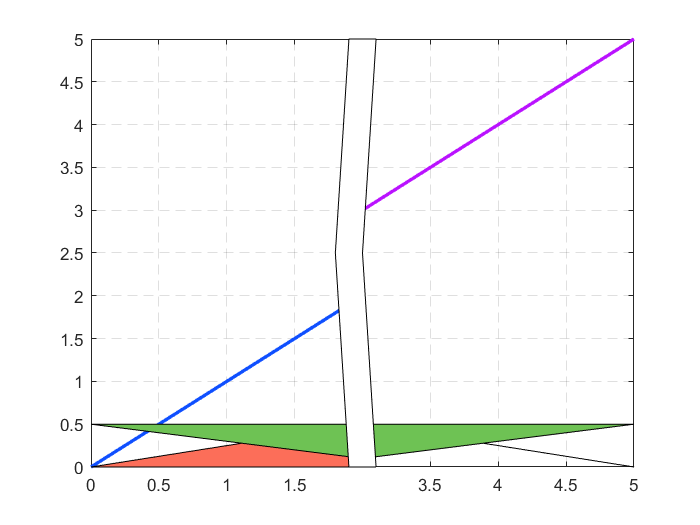

clear;clc;close all;
% 获取到颜色
[all_themes, all_colors] = GetColors(); 
x1 = 0:0.1:2;
y1 = x1;
x2 = 2:0.1:4;
y2 = x2 + 1;
ax = axes();
plot(x1, y1, 'Color', all_colors(19, :), 'LineWidth', 2);
hold on
plot(x2, y2, 'Color', all_colors(24, :), 'LineWidth', 2);
fill([0, 2, 2], [0, 0, 0.5], all_colors(1, :));
fill([2, 4, 2], [0.5, 0, 0.5], all_colors(1, :));
fill([0, 2, 2], [0.5, 0.1, 0.5], all_colors(3, :));
fill([2, 4, 2], [0.1, 0.5, 0.5], all_colors(3, :));
fill([1.9, 2.1, 2, 2.1, 1.9, 1.8], [0, 0, 2.5, 5, 5, 2.5], 'w');
hold off
% 设置一些属性
grid on
ax.XTickLabel = {'0', '0.5', '1', '1.5', '', '3.5', '4', '4.5', '5'};
ax.GridLineStyle = '--';